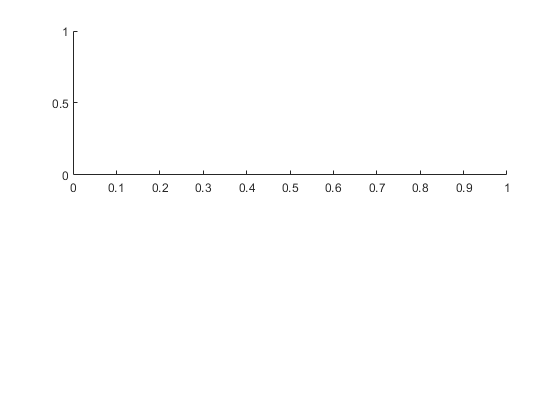

close all;
clear;
clc;

%File is a tab-delimited table of simulation results
%Row 1 contains headers
%Column 1 contains time values

%Generate an example in LTspice by running a simulation
% and choosing File -> Export data as text

%Navigate to folder that contains the csv/txt files
cd ../Desktop/

%Input files can be either csv or txt files

%LTS_V2 input file name
datafile = "out.csv";

%LTspice input file name (optional => replace with "" when no file)
datafile1 = "waveformTest.txt";


%First subplot
specificHeader = "v_2"; %Header of LTS_V2 data
specificHeader1 = "V(n002)"; %Header of LTspice data

graphTitle1 = "v_3"; %if graphTitle="", the column header name will be used
headerAxisName1 = "Voltage (V)";


%Second subplot
specificHeader2 = "i_F1"; %Header of LTS_V2 data
specificHeader3 = "I(F1)"; %Header of LTspice data

graphTitle2 = "I(F1)"; %if graphTitle="", the column header name will be used
headerAxisName2 = "Current (A)";


%Get LTS_V2 simulation data
if endsWith(datafile,".csv")
    simfile = importdata(datafile, ",", 1);
else
    simfile = importdata(datafile,'\t',1);
end
simdata = simfile.data;

%Get LTspice simulation data
if datafile1 == ""
    %do nothing
elseif endsWith(datafile1,".csv")
    simfile1 = importdata(datafile1, ",", 1);
    simdata1 = simfile1.data;
else
    simfile1 = importdata(datafile1,'\t',1);
    simdata1 = simfile1.data;
end




figure;

%First subplot:
subplot(2,1,1);


%Plot LTS_V2 data
for n = 2:(size(simdata, 2))
    if simfile.colheaders(n) == specificHeader
         plot(simdata(:,1),simdata(:,n)); %Add the data
         
         if graphTitle1 == ""
             title(simfile.colheaders(n));
         else
             title(graphTitle1);
         end
         
         ylabel(headerAxisName1);
         xlabel('Time (s)');
         break;
    end
end

Reference to non-existent field 'colheaders'.

hold on;

%Plot LTspice data on same axis
if datafile1 ~= ""
    for n = 2:(size(simdata1, 2))
        if simfile1.colheaders(n) == specificHeader1
             plot(simdata1(:,1),simdata1(:,n)); %Add the data
             break;
        end
    end
end
legend("LTS\_V2","LTspice");
hold off;


%Second subplot:
subplot(2,1,2);

%Plot LTS_V2 data
for n = 2:(size(simdata, 2))
    if simfile.colheaders(n) == specificHeader2
         plot(simdata(:,1),simdata(:,n)); %Add the data
         
         if graphTitle2 == ""
             title(simfile.colheaders(n));
         else
             title(graphTitle2);
         end
         
         ylabel(headerAxisName2);
         xlabel('Time (s)');
         break;
    end
end
hold on;

%Plot LTspice data on same axis
if datafile1 ~= ""
    for n = 2:(size(simdata1, 2))
        if simfile1.colheaders(n) == specificHeader3
             plot(simdata1(:,1),simdata1(:,n)); %Add the data
             break;
        end
    end
end
legend("LTS\_V2","LTspice");
hold off;